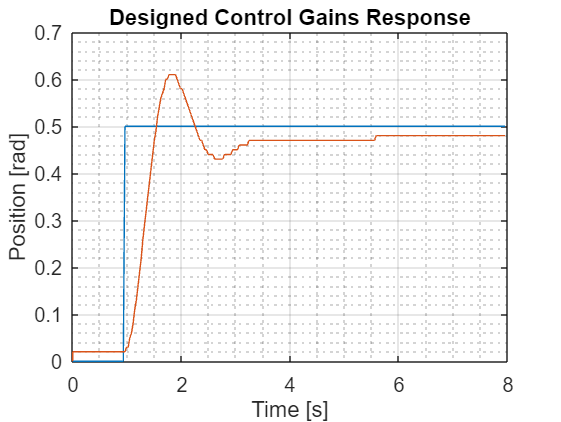

clc
clear

% Load Data
data = load("2023_10_13_002_TESTED_GAINS");
time = data(:,1); %[ms]
ref_pos = data(:,2); %[rad]
meas_pos = data(:,3); %[rad]

% Adjust/Convert Time Vector
time = time - time(2);
time(1) = 0;
time = time ./ 1000; %[s]

% Plot Data
figure();
plot(time,ref_pos)
hold on
plot(time,meas_pos)
hold off
ylabel('Position [rad]')
xlabel('Time [s]')
grid on; grid minor
title('Designed Control Gains Response')